# DataSet Preparation

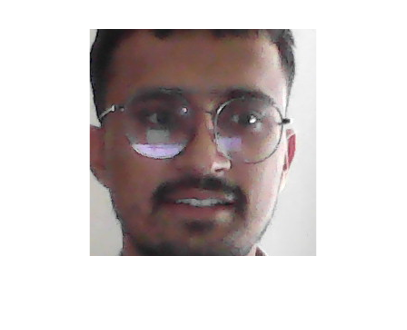

clc
close all


cam = webcam; % Accessing the webcam
faceDetector = vision.CascadeObjectDetector; % Accessing the Computer vision toolbox for object detection
c=500; % Setting up value for number of photos
temp=0;
while true
    e=cam.snapshot;
    bboxes =step(faceDetector,e); % Function to capture the photos
    if(sum(sum(bboxes))~=0)
        if(temp>=c)
            break;
        else
        es=imcrop(e,bboxes(1,:));
        es=imresize(es,[227 227]);  % Resizing the images of dataset
        filename=strcat(num2str(temp),'.bmp'); % renaming the images
        imwrite(es,filename);   % Saving the images
        temp=temp+1;
        imshow(es); % Displaying the images
        drawnow;
        end
    else
        imshow(e);
        drawnow;
    end
end